# Lab A: ML-Linear regression

## What is Machine Learnning?

We know that many mathematical problems have solid solutions which can be solved with a few equations. However, many real-world problems lack a complete solution, which is why Machine Learning (ML) was developed. Engineers use machine learning (ML) when they have data for unsolvable problems, such as face recognition. We, as humans, can recognize faces quickly and confidently; however, we still don't understand how our brain works to perform this action. There are billions of faces on the planet, each of which is made up of complex geometrical shapes.

Face recognition is thus a mathematical problem. We also learn to recognize more familiar faces (e.g., a friend or a TA) faster because our brain, a complex network of interconnected neurons, memorizes data and somehow discovers patterns on those faces while solving this mathematical problem.

ML accomplishes the same thing through mathematical algorithms. In this worksheet, we assume that two linear patterns exist between two datasets and use MATLAB and linear algebra to find them. Yes! That is machine learning, despite the fact that it appears to be in its early stages.

Remember from the pre-lab that we only need two variables to represent a line on a two-dimensional plane. In problem one, we will see that is sufficient to find a pattern among 10 randomly distributed noisy points. Consider how complicated patterns can be discovered with 200 variables! In practice, an ML algorithm may employ thousands or millions of such variables.

## Exercise 1 - linear regression

Create 10 points that are close to the line $x=y$ in range of $x\in \left(0,10\right)$, but not exactly the line. They have a random (noisy) distance of maximum $4$, as the equation below. You may refer to the pre-lab for further info.


$$y=x\;+\left(a\;\textrm{random}\;\textrm{number}\;\textrm{between}-4\;\textrm{to}\;4\right)$$


clear
N = 10;                     % numbr of points using to demonstrate a line
x = linspace(0, 10, N)   

x =             0       1.1111       2.2222       3.3333       4.4444       5.5556       6.6667       7.7778       8.8889           10


clf reset;
% your code here to find corresponding y and to plot the scattered data %
for i = 1:size(x,2)
    y(i) = x(i) + rand()*randi(8) - 4;
end

Use *scatter* function to visually check your data! the points must NOT be exactly on a line!

scatter(x,y)            %%%
hold on

To begin, keep in mind that our approach to linear regression today **differs slightly** from that of the lecture; however, if applied correctly, the result will be the same. At the end of this exercise, you should create a figure like the one below:

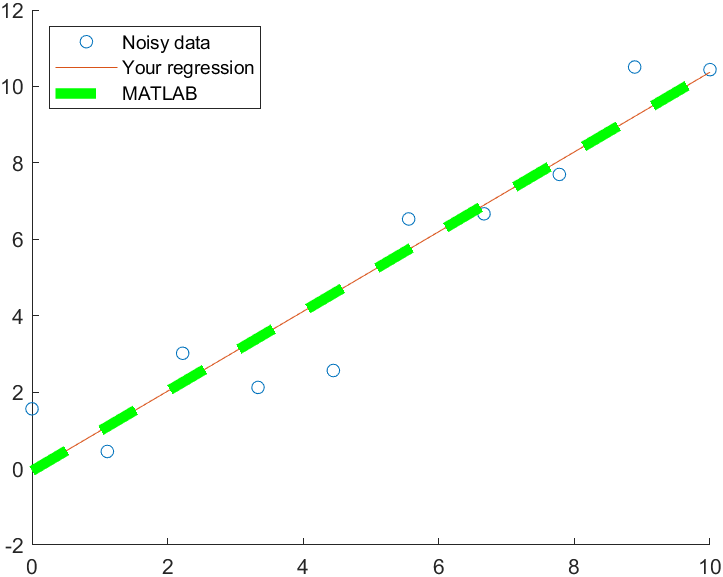

Now lets begin: hypothetically, we acknowledge there exists a linear pattern on the noisy dataset of length N, but we do not know this line (let's forget that we created it ourself for a few minutes). In order to find the linear pattern, we assume the general form of an equation$y=\textrm{ax}+b$ (as the pre-lab) and we find *a* and *b*. We also know that the best fitting line must have a minimum distance to all the points $\left(x_i ,y_i \right)\;i=1\;\textrm{to}\;N$simultaneously. For this goal, we consider the vertical distance of each point to the line. That is $|y-y_i |=|{\textrm{ax}}_{i\;} +b-y_i |$and we look for values of *a* and *b* that minimize the whole vertical distances, i.e. $L=\min \left(\;\;\sum_{i=1}^N |{\textrm{ax}}_{i\;} +b-y_i |\right)$. Of note, the vertical distance is not the same as the real [distance of any point](https://en.wikipedia.org/wiki/Distance_from_a_point_to_a_line); however, for simplicity, we continue to use the vertical one. Besides, instead of minimizing $L$, we minimize a new format of error that has a derivative. It is  known as the *least square error*: The less this error, the better line fitting on our data.


$$E=$$

$${\sum_{i=1}^N {\left({\textrm{ax}}_{i\;} +b-y_i \right)}^2 }^{\;}$$


The minimum value of $E$ corresponds to the best line that illustrates the linear behaviour of our data. For that, we take two derivatives and solve them for 0:


$$\frac{\partial }{\partial a}E=\;2\sum_{i=1}^N x_i \left({\textrm{ax}}_{i\;} +b-y_i \right)=0\Longrightarrow a\sum_{i=1}^N x_i^2 +b\sum_{i=1}^N x_i =\sum_{i=1}^N x_i y_i$$



$$\frac{\partial }{\partial a}E=\;2\sum_{i=1}^N \left({\textrm{ax}}_{i\;} +b-y_i \right)=0\Longrightarrow a\sum_{i=1}^N x_i +\textrm{bN}=\sum_{i=1}^N y_i$$


The above equation can be written in matrix form and solve for *a* and *b*, as


$$\left\lbrack \begin{array}{cc}
N & \sum_{i=1}^N x_i \\
\sum_{i=1}^N x_i  & \sum_{i=1}^N {x_i }^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
b\\
a
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_{i=1}^N y_i \\
\sum_{i=1}^N x_i y_{i\;} 
\end{array}\right\rbrack$$


Enter your code down here and find the 6 known parameters of the system above. Next, solve the system and plot it on your data:

A = zeros  (2); B = [];

Uncomment the two commands below. They give you a hint about the elements of A and B:

A(1,1) = 10

A =     10     0
     0     0


B(2,1) = sum(x.*y)

B =             0
       255.91


Now you can continue and updating elements of A and B as above:

A(1,2) = sum(x);
A(2,1) = sum(x);
A(2,2) = sum(x.*x);
A

A =            10           50
           50       351.85


B(1,1) = sum(y)

B =        32.736
       255.91


Plot the line generated after solving the system above for a and b, uncomenting the commands below:

line= A\B

line =       -1.2544
      0.90559


plot (x, line(2)*x + line(1))

Now compare your result with the MATLAB built-in function for linear regression (aka curve-fitting), uncommenting the code below:

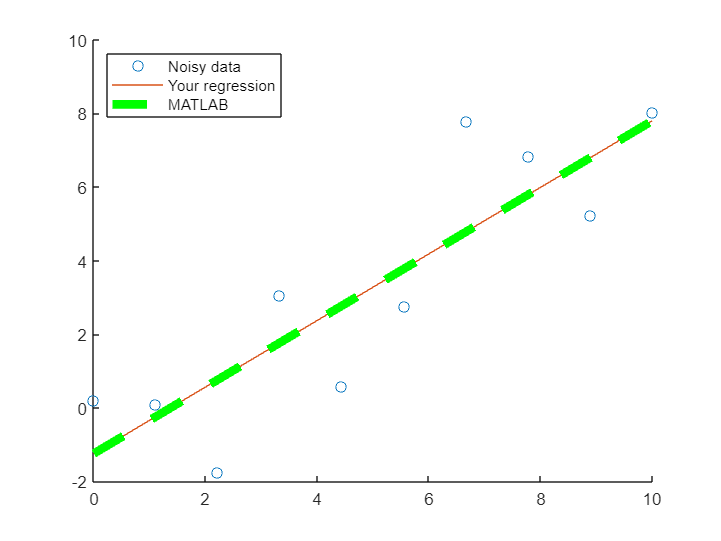

hold on
MATLAB = polyfit(x, y, 1);
plot(x, MATLAB(1)*x + MATLAB(2), 'Color', 'g','LineWidth', 5 , 'LineStyle','--')
legend('Noisy data', 'Your regression','MATLAB','Location','northwest')

Of note, there might be some difference because MATLAB utilizes an advanced curve-fitting algorithm. You can check the green scattered point to compare two regressions. In addition, **try to increase *****N*** and observe the improvements of the two regressions. The more data you provide, the closer your ML output to the line $y=x$.

## Exercise 2

We read data from a comma-separated values (CSV) file in this exercise. Please download and save [this file](https://www.dropbox.com/s/qspy8vo6v27d7uz/data.csv?dl=0) in the same directory as your worksheet. Before returning to the worksheet, open the csv file in notepad (or any other text editor) and examine its structure. It uses commas and semi-colons to separate data, just like MATLAB. You will notice two columns if you open the same file in MS Excel or MATLAB. The first column contains x values, while the second contains y values.

In this exercise, you will use linear regression to fit a parabola (a second-order polynomial) to these x and y values. Following that, you compare your results to the output of the MATLAB built-in function.

You can start reading the data with the syntax below:

clf

data = readtable('T4_E1_data.csv')

Error using readtable (line 498)
Unable to find or open 'T4_E1_data.csv'. Check the path and filename or file permissions.

Lets scatter the data we just read to visually check their distribution:

x = data.Var1;
y = data.Var2;
scatter(x,y)
hold on

The regression system of equation for a parabola $y={\textrm{Ax}}^{2\;} +{\textrm{By}}^2 +C\;$has the matrix form as below. Use it to derive your own curve-fit code:


$$\left\lbrack \begin{array}{ccc}
N & \sum_{i=1}^N x_i  & \sum_{i=1}^N {x^2 }_i \\
\sum_{i=1}^N x_i  & \sum_{i=1}^N {x^2 }_i  & \sum_{i=1}^N {x^3 }_i \\
\sum_{i=1}^N {x^2 }_i  & \sum_{i=1}^N {x^3 }_i  & \sum_{i=1}^N {x^4 }_i 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C\\
B\\
A
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_{i=1}^N y_i \\
\sum_{i=1}^N {y_i \;x}_i \\
\sum_{i=1}^N {y_i \;x^2 }_i 
\end{array}\right\rbrack$$


% your code here to read the second column %
A = [40 sum(x) sum(x.*x); sum(x) sum(x.*x) sum(x.*x.*x); sum(x.*x) sum(x.*x.*x) sum(x.*x.*x.*x)]
B = [sum(y); sum(y.*x); sum(y.*x.*x)]

Let's plot the result of our parabolic regression:

% Your code here to plot the scattered data and your parabola %
line= A\B
plot (x, line(3).*x.*x + line(2).*x + line(1))
hold on

Now, try to find the MATLAB built-in function using help. Your final figure should be similar to the one below:

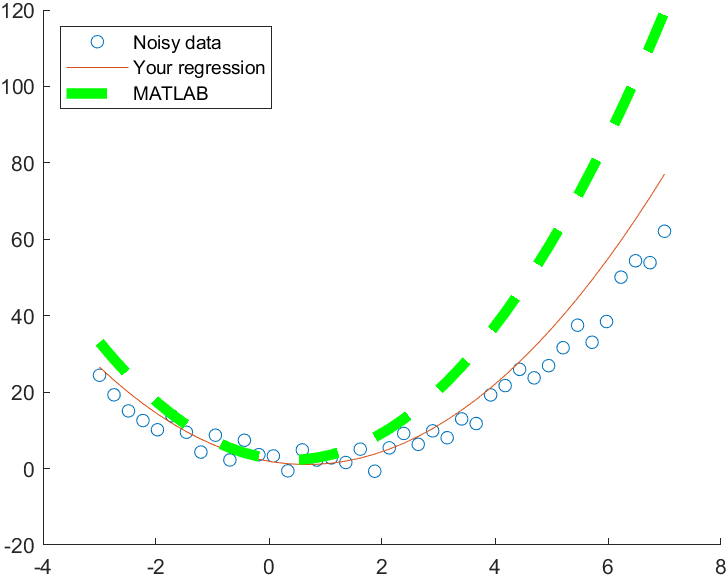

Take note that your regression has a lower chance of being the same as MATLAB's this time. This is normal because MATLAB uses more complex algorithms. A uniform noise is also a linear noise, and a parabolic regression would not be the best fit to such a noise. You may observe this fact, too.

MATLAB = polyfit(x, y, 2);
plot(x, MATLAB(1).*x.*x + MATLAB(2).*x + MATLAB(3), 'Color', 'g','LineWidth', 5 , 'LineStyle','--')
legend('Noisy data', 'Your regression','MATLAB','Location','northwest')